## **Simplified case **

**Bar fixed at one end and loaded at the other end with 1 MPa on that face. The bar has Ergal as material. **

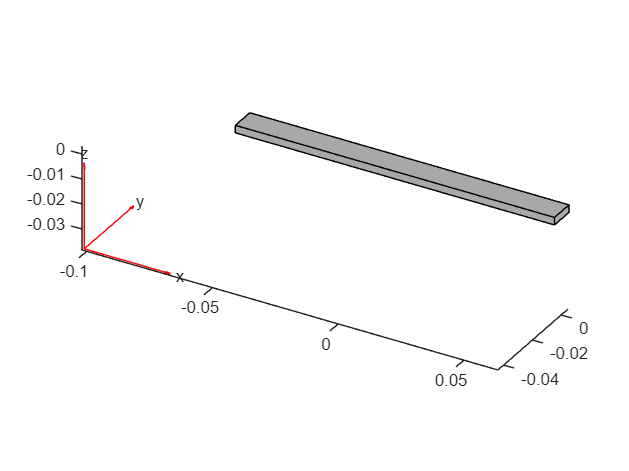

% Geometry

L = 127e-3; % m
W = 10e-3; % m
H = 3e-3; % m
g = multicuboid(L,W,H);

figure
pdegplot(g)

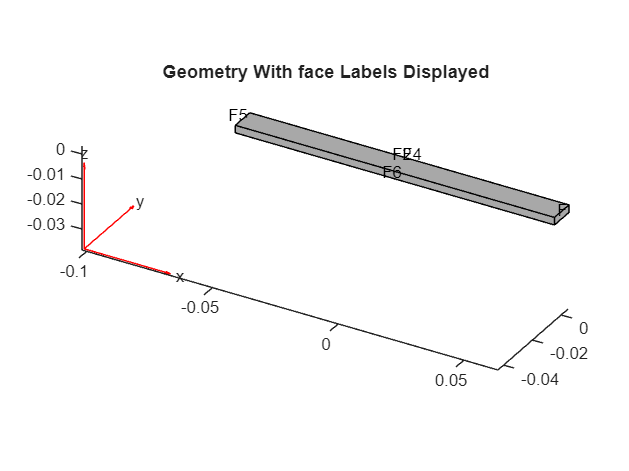


figure; 
pdegplot(g,FaceLabels="on"); 
axis equal
title("Geometry With face Labels Displayed")   % I need it to select the faces 

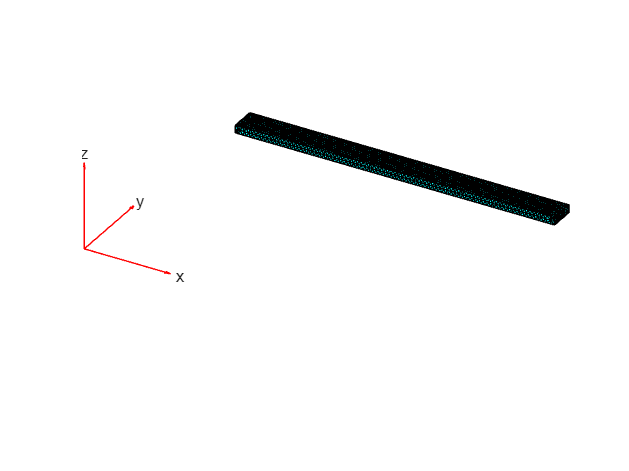


model = femodel(AnalysisType="structuralModal", ....
                Geometry=g);

% Mesh 
hmax = H/2;
model = generateMesh(model,Hmax=hmax);
pdemesh(model)


% Material properties
E = 7.17e+10; %Pa
nu = 0.33; 
rho = 2.81e3; %kg/m^3
model.MaterialProperties = ...
    materialProperties(YoungsModulus=E, ...
                       PoissonsRatio=nu, ...
                       MassDensity=rho);

Constraint

model.FaceBC(5) = faceBC(Constraint="fixed");

**Modal Analysis (no loads are necessary)**

res = solve(model,FrequencyRange=[-0.1,1e6'])

res =   ModalStructuralResults with properties:

    NaturalFrequencies: [77×1 double]
            ModeShapes: [1×1 FEStruct]
                  Mesh: [1×1 FEMesh]



modeID = 1:numel(res.NaturalFrequencies);

tmodalResults = table(modeID.',res.NaturalFrequencies/(2*pi));
tmodalResults.Properties.VariableNames = {'Mode','Frequency'};
disp(tmodalResults)

    Mode    Frequency 
    ____    __________

      1         152.51
      2         504.68
      3         953.22
      4           2659
      5         3074.7
      6         3211.6
      7         5183.1
      8           8260
      9         8510.9
     10         9656.3
     11         9962.1
     12          12611
     13          15340
     14          16159
     15          17448
     16          22764
     17          22981
     18          23874
     19          29166
     20          29501
     21          29869
     22          33462
     23          35955
     24          36401
     25          43304
     26          43487
     27          43806
     28          49720
     29          50784
     30          51166
     31          54686
     32          58309
     33          59495
     34          65944
     35          66066
     36          68250
     37          69472
     38          74062
     39    

Selection of the system's first natural **frequency** and the corresponding **period** for sampling (the identical frequency was found in Creo9) 

freqNumerical = res.NaturalFrequencies(1)/(2*pi)

freqNumerical = 152.5064

longestPeriod = 1/freqNumerical

longestPeriod = 0.0066

**Static Analysis**

model.AnalysisType="structuralStatic";

% Load
model.FaceLoad(3) = faceLoad(SurfaceTraction=[0;0;1e6]); % 1MPa of traction in z direction
Rstatic = solve(model)

Rstatic =   StaticStructuralResults with properties:

      Displacement: [1×1 FEStruct]
            Strain: [1×1 FEStruct]
            Stress: [1×1 FEStruct]
    VonMisesStress: [15853×1 double]
              Mesh: [1×1 FEMesh]


**Dynamic Analysis**

model.AnalysisType = "structuralTransient";
model.FaceLoad = [];
model.CellIC = cellIC(Displacement=Rstatic); % Takes the displacement of the previous static analysis as input
tlist = 0:longestPeriod/100:10*longestPeriod

tlist =          0    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0007    0.0007    0.0008    0.0009    0.0009    0.0010    0.0010    0.0011    0.0012    0.0012    0.0013    0.0014    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0018    0.0019    0.0020    0.0020    0.0021    0.0022    0.0022    0.0023    0.0024    0.0024    0.0025    0.0026    0.0026    0.0027    0.0028    0.0028    0.0029    0.0030    0.0030    0.0031    0.0031    0.0032


resyxrT = solve(model,tlist,ModalResults=res);


**--> Undamped** solution

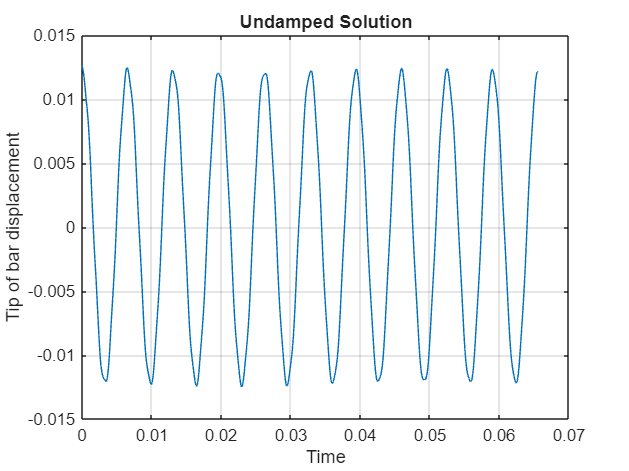

intrpUt = interpolateDisplacement(resyxrT,[63.5e-3;0;1.5e-3]);  % at the end of the bar
plot(resyxrT.SolutionTimes,intrpUt.uz)
grid on
title("Undamped Solution")
xlabel("Time")
ylabel("Tip of bar displacement")  

**--> Damped** solution with 3% of damping factor

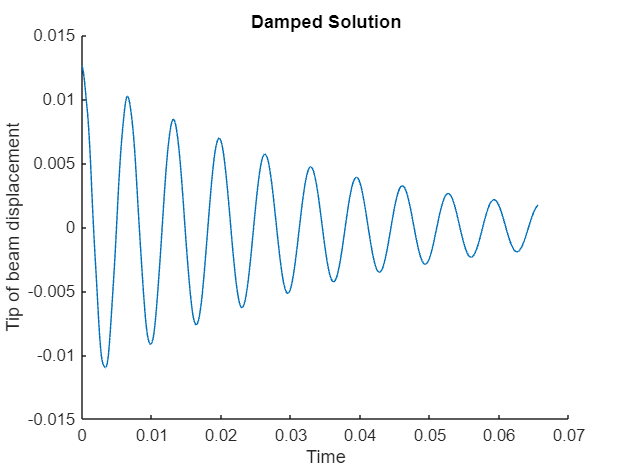

zeta = 0.03;  % 3% damping factor
omega = 2*pi*freqNumerical;
resyxrT = solve(model,tlist, ...
             ModalResults=res, ...
             DampingZeta=zeta);
intrpUt = interpolateDisplacement(resyxrT,[63.5e-3;0;1.5e-3]);  % at the end of the bar
figure
hold on
plot(resyxrT.SolutionTimes,intrpUt.uz)

title("Damped Solution")
xlabel("Time")
ylabel("Tip of beam displacement")